load detectionHistoryYOLO;

videoIn = VideoReader("MathWorksTraffic.mp4");
videoOut = VideoWriter("TrackingResults.avi");

videoOut.FrameRate = videoIn.FrameRate;
numFrames = videoIn.NumFrames;

tracks = table();
analysisResults = table();

params.costOfNonAssignment = 200;
params.confirmationThreshold = 5;
params.lostThreshold = 10;

params.ageThreshold = 10;
params.visibilityThreshold = 0.6;

params.InitialEstimateError = [200, 50];
params.MotionNoise = [100, 25];
params.MeasurementNoise = 100;

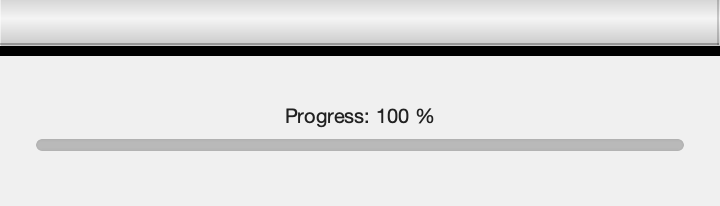

open(videoOut);

of = opticalFlowFarneback;
f = waitbar(0, 'Starting');

for frameIdx = 1:numFrames
    frame = read(videoIn, frameIdx);

    detections = detectionsHistory{frameIdx};
    % detections = detectCars(frame, of);

    detections.Centroids = detections.Centroid;

    tracks = predictTracks(tracks);

    [tracks, detections] = assignTracksDetections(detections, tracks, params);

    tracks = updateTracks(tracks, detections, params);

    analysisResults = analyzeConfirmedTracks(tracks, analysisResults, frameIdx);

    writeTrackingResults(frame, tracks, videoOut);
    waitbar(frameIdx/numFrames, f, sprintf('Progress: %d %%', floor(frameIdx/numFrames*100)));
end


close(videoOut);

clear functions

analysisResults

analysisResults = 29×2 table
    ConfirmedTrackId    ConfirmedFrame
    ________________    ______________

            3                  7      
            6                 99      
           10                134      
           35                191      
           53                199      
           54                201      
           55                201      
           56                203      
           58                207      
           59                208      
           66                213      
           68                213      
           79                242      
           80                246      
          100                256      
          102                256      


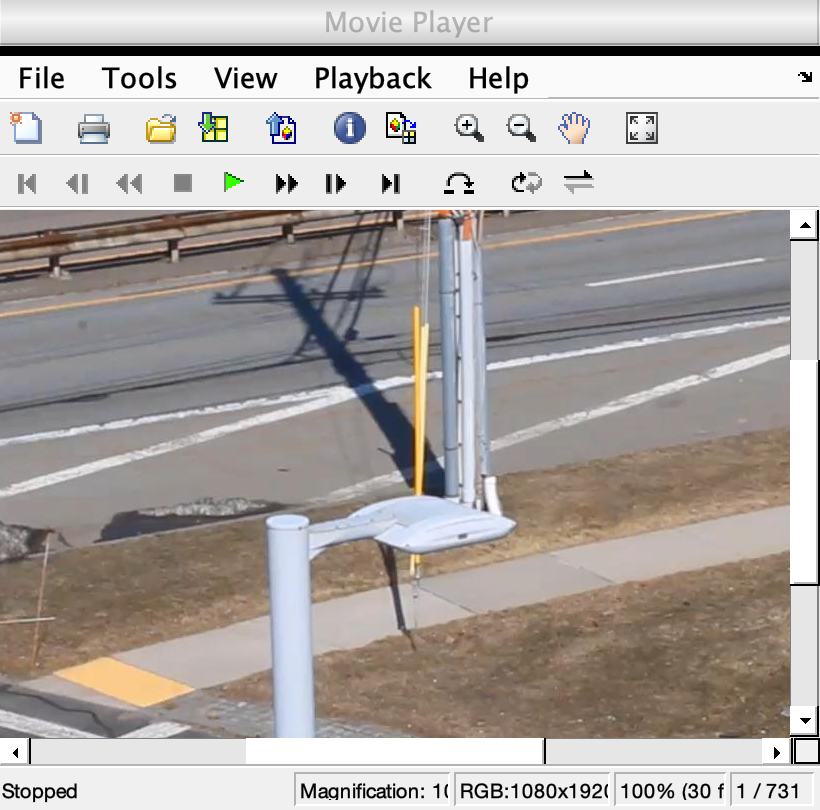

% v = VideoReader("TrackingResults.avi");
implay("TrackingResults.avi");

function detections = detectCars(frame, of)
    flow = estimateFlow(of, im2gray(frame));
    mask = (flow.Magnitude > 1);
    mask = bwareafilt(mask, [500, Inf]);
    se = strel("disk", 20, 0);
    mask = imclose(mask, se);
    detections = regionprops("table",mask,flow.Vx,["MeanIntensity","BoundingBox", "Centroid"]);
end

function tracks = predictTracks(tracks)
    for idx = 1:height(tracks)
        [tracks.PredictedLocation(idx, :), tracks.PredictedState(idx, :)] = predict(tracks.KalmanFilter{idx});
    end
end


function [tracks, detections] = assignTracksDetections(detections, tracks, params)
    cost = zeros(height(tracks), height(detections));
    for idx = 1:height(tracks)
        cost(idx, :) = distance(tracks.KalmanFilter{idx}, detections.Centroids);
    end

    costOfNonAssignment = params.costOfNonAssignment;
    assignedIdxPairs = assignDetectionsToTracks(cost, costOfNonAssignment);

    if ~isempty(tracks)
        tracks.Visible(:) = false;
        tracks.Visible(assignedIdxPairs(:, 1)) = true;
        tracks.DetectedLocation(assignedIdxPairs(:,1), :) = detections.Centroids(assignedIdxPairs(:, 2), :);
    end

    if ~isempty(detections)
        detections.assigned(:) = false;
        detections.assigned(assignedIdxPairs(:,2)) = true;
    end
end

function tracks = updateTracks(tracks, detections, params)
    persistent TrackId;
    if isempty(TrackId)
        TrackId = 1;
    end

    for idx = 1:height(tracks)
        if tracks.Visible(idx)
            [tracks.TrackedLocation(idx, :), tracks.TrackedState(idx, :)] = correct(tracks.KalmanFilter{idx}, tracks.DetectedLocation(idx, :));
        end
    end

    if ~isempty(tracks)
        tracks.TrackedLocation(~tracks.Visible, :) = tracks.PredictedLocation(~tracks.Visible, :);
        tracks.Age = tracks.Age + 1;
        tracks.TotalVisibleCount(tracks.Visible) = tracks.TotalVisibleCount(tracks.Visible) + 1;
        tracks.Confirmed = tracks.TotalVisibleCount > params.confirmationThreshold;
        tracks.ConsecutiveInvisibleCount(tracks.Visible) = 0;
        tracks.ConsecutiveInvisibleCount(~tracks.Visible) = tracks.ConsecutiveInvisibleCount(~tracks.Visible) + 1;
        visibility = tracks.TotalVisibleCount./tracks.Age;
        newInds = tracks.Age <= params.ageThreshold;
        lowVisibilityInds = visibility < params.visibilityThreshold;
        lostInds = tracks.ConsecutiveInvisibleCount >= params.lostThreshold;
        deleteInds = (newInds & lowVisibilityInds) | lostInds;
        tracks = tracks(~deleteInds, :);
    end

    for idx = 1:height(detections)
        if ~detections.assigned(idx)
            KalmanFilter = configureKalmanFilter("ConstantVelocity", detections.Centroids(idx,:), params.InitialEstimateError, params.MotionNoise, params.MeasurementNoise);
            KalmanFilter = {KalmanFilter};

            DetectedLocation = detections.Centroids(idx, :);
            TrackedLocation = DetectedLocation;
            PredictedLocation = DetectedLocation;
            PredictedState = zeros(1, 4);
            TrackedState = zeros(1,4);
            Age = 1;
            TotalVisibleCount = 1;
            ConsecutiveInvisibleCount = 1;
            Visible = true;
            Confirmed = false;

            newTrack = table(TrackId, DetectedLocation, TrackedLocation, ...
                PredictedLocation, PredictedState, TrackedState, KalmanFilter, ...
                Age, TotalVisibleCount, ConsecutiveInvisibleCount, Visible, Confirmed);

            tracks = [tracks; newTrack];

            TrackId = TrackId + 1;
        end
    end
end

function results = analyzeConfirmedTracks(tracks,results,frameNumber)

    for idx = 1:height(tracks)
        % Only add confirmed tracks to the results table
        % tracks.Confirmed is a logical variable.
        if  tracks.Confirmed(idx)
            
            % If results table is empty, add a new row to the table
            if isempty(results) 

                % Initialize a new row for the results 
                ConfirmedTrackId = tracks.TrackId(idx);
                ConfirmedFrame = frameNumber;
                newRow = table(ConfirmedTrackId,ConfirmedFrame); 

                % Add the new row to the results table  
                results = [results; newRow]; 

            % If tracks exist, check if the current track is already
            % confirmed and in the tracks table. If not, add it.
            elseif ~ismember(tracks.TrackId(idx),results.ConfirmedTrackId)

                ConfirmedTrackId = tracks.TrackId(idx);
                ConfirmedFrame = frameNumber;
                newRow = table(ConfirmedTrackId,ConfirmedFrame); 

                % Add the new row to the results table  
                results = [results; newRow];

            end

        end
    end
 
end

function writeTrackingResults(frame,tracks,videoOut)

    if ~isempty(tracks)
        % Extract the confirmed tracks
        displayTracks = tracks(tracks.Confirmed,:); 
    
        if ~isempty(displayTracks) 
            % Add labels to tracks and display them near locations 
            labels = "Track " + displayTracks.TrackId; 
            frame = insertText(frame,displayTracks.TrackedLocation,labels,"boxcolor","green");
        end
    end
   
    writeVideo(videoOut,frame); 

end